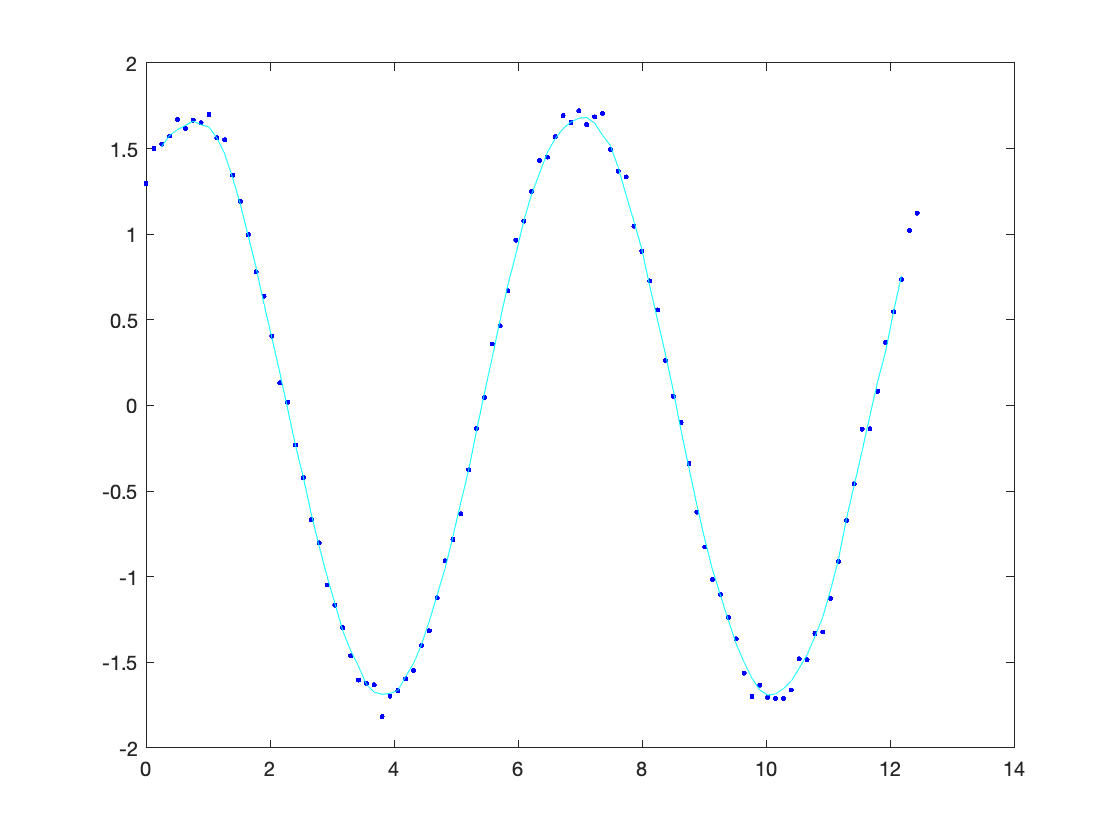

x = linspace(0,2*pi)*2;
x = x(1:(end-1));
y = (1+rand(1)) * sin(x+rand(1)) + randn(size(x)) * 0.05;

% Make a window function
% The following window is 5 elements wide
w = ones([1, 5]);
w = w/sum(w);

yf = conv(y, w, 'valid'); % filter
xf = conv(x, w, 'valid'); % filter

plot(x,y,'.b',xf,yf,'-c') % plot for visual confirmation